clear all
x = [-3;-2;-1;1;4;7;15;15.1;15.2;16;17;18;19;20];

exp_err = readtable ('Ce_run1_errors.xlsx', "ReadRowNames",true)

exp_err = 177×22 table
              SampleId          R          AcquisitionTime         QCStatus                                                         DatasetFile                                                                                                     MethodFile                                                     Na23         Mg24       Si29        Cl35         K39         Ca43         Sr88      Rh103_IS_     Cs133      In115_IS_     La139       Ce140       Pb208      Re185_IS_     Ce_1140     Re_1185_IS_
          ________________    _____    ___________________

exp_data = readtable ('Ce_run1_concentrations.xlsx', "ReadRowNames",true)

exp_data = 177×22 table
                 SampleId             R          AcquisitionTime         QCStatus                                                         DatasetFile                                                                                                     MethodFile                                                  Na23_counts_    Mg24_counts_    Si29_counts_    Cl35_counts_    K39_counts_    Ca43_counts_    Sr88_counts_    Rh103_IS__counts_    Cs133_counts_    In115_IS__counts_    La139_counts_    Ce140_counts_    Pb208_counts_    Re185_IS__counts_    Ce_1140_counts_    Re_1185_IS__counts_
          <

Defining sample numbers into sets

pellet_4h14K1 = ["EP1";"EP9";"EP17";"EP25";"EP36";"EP47";"EP58";"EP69";"EP80"; "EP91";"EP100";"EP109";"EP118";"EP127"];
pellet_4h14K2 = ["EP2";"EP10";"EP18";"EP26";"EP37";"EP48";"EP59";"EP70";"EP81"; "EP92";"EP101";"EP110";"EP119";"EP128"];
pellet_4h16K1 = ["EP3";"EP11";"EP19";"EP27";"EP38";"EP49";"EP60";"EP71";"EP82"; "EP93";"EP102";"EP111";"EP120";"EP129"];
pellet_4h16K2 = ["EP4";"EP12";"EP20";"EP28";"EP39";"EP50";"EP61";"EP72";"EP83"; "EP94";"EP103";"EP112";"EP121";"EP130"];
pellet_2h16K1 = ["EP5";"EP13";"EP21";"EP29";"EP40";"EP51";"EP62";"EP73";"EP84"; "EP95";"EP104";"EP113";"EP122";"EP131"];
pellet_2h16K2 = ["EP6";"EP14";"EP22";"EP30";"EP41";"EP52";"EP63";"EP74";"EP85"; "EP96";"EP105";"EP114";"EP123";"EP132"];
pellet_2h12K1 = ["EP7";"EP15";"EP23";"EP31";"EP42";"EP53";"EP64";"EP75";"EP86"; "EP97";"EP106";"EP115";"EP124";"EP133"];
pellet_2h12K2 = ["EP8";"EP16";"EP24";"EP32";"EP43";"EP54";"EP65";"EP76";"EP87"; "EP98";"EP107";"EP116";"EP125";"EP134"];
pellet_blank1 = ["Std Zero";"Std Zero";"Std Zero";"EP33";"EP44";"EP55";"EP66";"EP77";"EP88"; "EP99";"EP108";"EP117";"EP126";"EP135"];
pellet_blank2 = ["Std Zero";"Std Zero";"Std Zero";"EP34";"EP45";"EP56";"EP67";"EP78";"EP89";"Std Zero";"Std Zero";"Std Zero";"Std Zero";"Std Zero"];
pellet_blank3 = ["Std Zero";"Std Zero";"Std Zero";"EP35";"EP46";"EP57";"EP68";"EP79";"EP90";"Std Zero";"Std Zero";"Std Zero";"Std Zero";"Std Zero"];

Toggle different graphs for a quick look

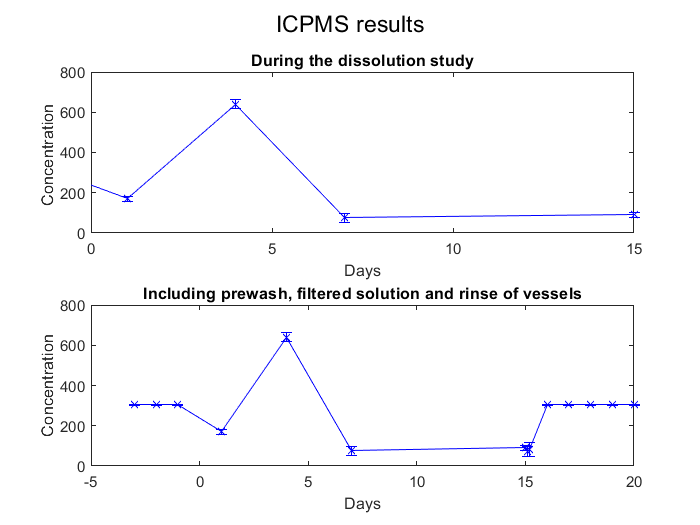

Set = pellet_blank2;
Element = 21;
conc = [];
errpercent =[];

for i = 1:size(Set) 
    s = find(strcmp(Set(i),exp_data{:,1}));
    conc = [conc; exp_data{s,Element}];
    errpercent= [errpercent; exp_err{(s-1),Element}];
end

error = conc .* errpercent;


clf
subplot(2,1,1)

errorbar(x,conc,error, 'bx-')
title('During the dissolution study')
xlabel('Days')
ylabel('Concentration ')
xlim ([0 15])


subplot(2,1,2)
errorbar(x,conc,error, 'bx-')
title('Including prewash, filtered solution and rinse of vessels')
xlabel('Days')
ylabel('Concentration')
hold off

sgtitle('ICPMS results - uncorrected for background, wrong units')

Toggle for a quick comparison

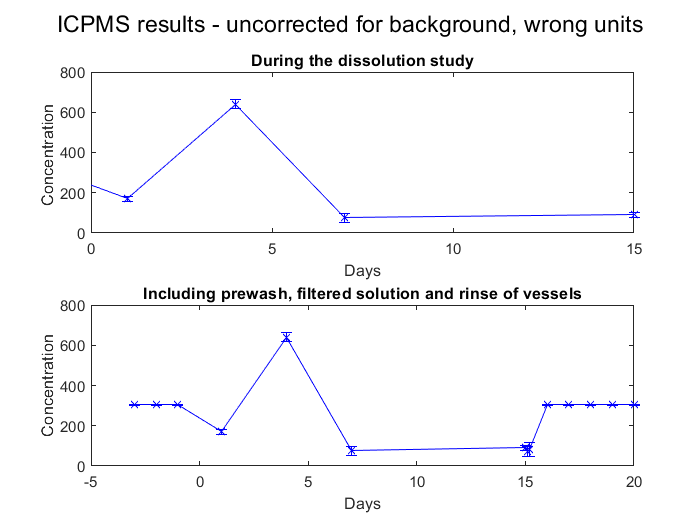

Set1 = pellet_blank2;
Set2 = pellet_blank1;
Set3 = pellet_blank3;


Element = 21;
conc = [];
errpercent =[];

for i = 1:size(Set) 
    s = find(strcmp(Set(i),exp_data{:,1}));
    conc = [conc; exp_data{s,Element}];
    errpercent= [errpercent; exp_err{(s-1),Element}];
end

error = conc .* errpercent;


clf
subplot(2,1,1)

errorbar(x,conc,error, 'bx-')
title('During the dissolution study')
xlabel('Days')
ylabel('Concentration ')
xlim ([0 15])


subplot(2,1,2)
errorbar(x,conc,error, 'bx-')
title('Including prewash, filtered solution and rinse of vessels')
xlabel('Days')
ylabel('Concentration')
hold off

sgtitle('ICPMS results - uncorrected for background, wrong units')

so I need to get them all in mg/L and I need to take off the COx background amount of ceria....

Ce_conc_4h14K1 =[];
Ce_errpercent_4h14k1 = [];
Samplenumbers_4h14K1 = ["EP1";"EP9";"EP17";"EP25";"EP36";"EP47";"EP58";"EP69";"EP80"; "EP91";"EP100";"EP109";"EP118";"EP127"];



for i = 1:size(Samplenumbers_4h14K1) 
    s = find(strcmp(Samplenumbers_4h14K1(i),exp_data{:,1}));
    Ce_conc_4h14K1 = [Ce_conc_4h14K1; exp_data{s,21}];
    Ce_errpercent_4h14k1= [Ce_errpercent_4h14k1; exp_err{(s-1),21}];
end

Ce_err_4h14k1 = Ce_conc_4h14K1 .* Ce_errpercent_4h14k1;

Ce_conc_4h14K2 =[];
Ce_errpercent_4h14k2 = [];
Samplenumbers_4h14K2 = ["EP2";"EP10";"EP18";"EP26";"EP37";"EP48";"EP59";"EP70";"EP81"; "EP92";"EP101";"EP110";"EP119";"EP128"];

for i = 1:size(Samplenumbers_4h14K2) 
    s = find(strcmp(Samplenumbers_4h14K2(i),exp_data{:,1}));
    Ce_conc_4h14K2 = [Ce_conc_4h14K2; exp_data{s,21}];
    Ce_errpercent_4h14k2= [Ce_errpercent_4h14k2; exp_err{(s-1),21}];
end

Ce_err_4h14k2 = Ce_conc_4h14K2 .* Ce_errpercent_4h14k2;


clf
subplot(2,1,1)

errorbar(x,Ce_conc_4h14K1,Ce_err_4h14k1, 'bx-')
title('During the dissolution study')
xlabel('Days')
ylabel('Ceria Concentration (pg/ml)')
xlim ([0 15])
hold on
errorbar(x,Ce_conc_4h14K2,Ce_err_4h14k2, 'rx-')
legend('4h14k1','4h14k2',"Location","best")

subplot(2,1,2)
errorbar(x,Ce_conc_4h14K1,Ce_err_4h14k1, 'bx-')
title('Including prewash, filtered solution and postwash')
xlabel('Days')
ylabel('Ceria Concentration (pg/ml)')
%xlim ([0 15])
hold on
errorbar(x,Ce_conc_4h14K2,Ce_err_4h14k2, 'rx-')
legend('4h14k1','4h14k2',"Location","best")
hold off

sgtitle('ICPMS results for ceria pellets sintered at 1400 ^oC')

4 hours 16 degrees

Ce_conc_4h16K1 =[];
Ce_errpercent_4h16k1 = [];
Samplenumbers_4h16K1 = ["EP3";"EP11";"EP19";"EP27";"EP38";"EP49";"EP60";"EP71";"EP82"; "EP93";"EP102";"EP111";"EP120";"EP129"];

for i = 1:size(Samplenumbers_4h16K1) 
    s = find(strcmp(Samplenumbers_4h16K1(i),exp_data{:,1}));
    Ce_conc_4h16K1 = [Ce_conc_4h16K1; exp_data{s,21}];
    Ce_errpercent_4h16k1= [Ce_errpercent_4h16k1; exp_err{(s-1),21}];
end

Ce_err_4h16k1 = Ce_conc_4h16K1 .* Ce_errpercent_4h16k1;

Ce_conc_4h16K2 =[];
Ce_errpercent_4h16k2 = [];
Samplenumbers_4h16K2 = ["EP4";"EP12";"EP20";"EP28";"EP39";"EP50";"EP61";"EP72";"EP83"; "EP94";"EP103";"EP112";"EP121";"EP130"];

for i = 1:size(Samplenumbers_4h16K2) 
    s = find(strcmp(Samplenumbers_4h16K2(i),exp_data{:,1}));
    Ce_conc_4h16K2 = [Ce_conc_4h16K2; exp_data{s,21}];
    Ce_errpercent_4h16k2= [Ce_errpercent_4h16k2; exp_err{(s-1),21}];
end

Ce_err_4h16k2 = Ce_conc_4h16K2 .* Ce_errpercent_4h16k2;

clf 

subplot(2,1,1)

errorbar(x,Ce_conc_4h16K1,Ce_err_4h16k1, 'bx-')
title('During the dissolution study')
xlabel('Days')
ylabel('Ceria Concentration (pg/ml)')
xlim ([0 15])
hold on
errorbar(x,Ce_conc_4h16K2,Ce_err_4h16k2, 'rx-')
legend('4h16k1','4h16k2',"Location","best")

subplot(2,1,2)
errorbar(x,Ce_conc_4h16K1,Ce_err_4h16k1, 'bx-')
title('Including prewash, filtered solution and postwash')
xlabel('Days')
ylabel('Ceria Concentration (pg/ml)')
%xlim ([0 15])
hold on
errorbar(x,Ce_conc_4h16K2,Ce_err_4h16k2, 'rx-')
legend('4h16k1','4h16k2',"Location","best")
hold off

sgtitle('ICPMS results for ceria pellets sintered at 1600 ^oC for 4 hours')

clf

subplot(2,1,1)
errorbar(x,Ce_conc_4h16K1,Ce_err_4h16k1, 'gx-')
title('During the dissolution study')
xlabel('Days')
ylabel('Ceria Concentration (pg/ml)')
xlim ([0 15])
hold on
errorbar(x,Ce_conc_4h14K1,Ce_err_4h14k1, 'kx-')
legend('4h16k1','4h14k1',"Location","best")

subplot(2,1,2)
errorbar(x,Ce_conc_4h16K1,Ce_err_4h16k1, 'gx-')
title('During the dissolution study')
xlabel('Days')
ylabel('Ceria Concentration (pg/ml)')
%xlim ([0 15])
hold on
errorbar(x,Ce_conc_4h14K1,Ce_err_4h14k1, 'kx-')
legend('4h16k1','4h14k1',"Location","best")



correct for the background Ce in COx